clearvars
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')

% % Casts 
cast06 = readSBScnv( 'ar69-01_006_hyst.cnv' );
cast07 = readSBScnv( 'ar69-01_007_hyst.cnv' );
cast08 = readSBScnv( 'ar69-01_008_hyst.cnv' );
cast09 = readSBScnv( 'ar69-01_009_hyst.cnv' );
cast10 = readSBScnv( 'ar69-01_010_hyst.cnv' );
cast11 = readSBScnv( 'ar69-01_011_hyst.cnv' );
cast12 = readSBScnv( 'ar69-01_012_hyst.cnv' );
cast13 = readSBScnv( 'ar69-01_013_hyst.cnv' );
cast14 = readSBScnv( 'ar69-01_014_hyst.cnv' );
cast15 = readSBScnv( 'ar69-01_015_hyst.cnv' );
cast16 = readSBScnv( 'ar69-01_016_hyst.cnv' );
cast17 = readSBScnv( 'ar69-01_017_hyst.cnv' );
cast18 = readSBScnv( 'ar69-01_018_hyst.cnv' );
cast19 = readSBScnv( 'ar69-01_019_hyst.cnv' );
cast20 = readSBScnv( 'ar69-01_020_hyst.cnv' );
cast21 = readSBScnv( 'ar69-01_021_hyst.cnv' );
cast22 = readSBScnv( 'ar69-01_022_hyst.cnv' );
cast23 = readSBScnv( 'ar69-01_023_hyst.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')

btl = readtable('Irminger_Sea-09_AR69-01_CTD_Sampling_Summary_KF.xlsx','TextType','string');
btl.Cast = double(btl.Cast); btl.Bottle = double(btl.Bottle);
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum14 = btl(btl.Cast == 14,:);
btlsum16 = btl(btl.Cast == 16,:);
btlsum17 = btl(btl.Cast == 17,:);
btlsum18 = btl(btl.Cast == 18,:);
btlsum19 = btl(btl.Cast == 19,:);
btlsum20 = btl(btl.Cast == 20,:);
btlsum21 = btl(btl.Cast == 21,:);
btlsum22 = btl(btl.Cast == 22,:);

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year9')
btl14 = readtable('ar69-01_014_hyst.csv','TextType','string');

btl16 = readtable('ar69-01_016_hyst.csv','TextType','string');

btl17 = readtable('ar69-01_017_hyst.csv','TextType','string');

btl18 = readtable('ar69-01_018_hyst.csv','TextType','string');

btl19 = readtable('ar69-01_019_hyst.csv','TextType','string');

btl20 = readtable('ar69-01_020_hyst.csv','TextType','string');

btl21 = readtable('ar69-01_021_hyst.csv','TextType','string');

btl22 = readtable('ar69-01_022_hyst.csv','TextType','string');


% Join tables 
btlsum14 = join(btl14,btlsum14,'Keys',"Bottle");
btlsum16 = join(btl16,btlsum16,'Keys',"Bottle");
btlsum17 = join(btl17,btlsum17,'Keys',"Bottle");
btlsum18 = join(btl18,btlsum18,'Keys',"Bottle");
btlsum19 = join(btl19,btlsum19,'Keys',"Bottle");
btlsum20 = join(btl20,btlsum20,'Keys',"Bottle");
btlsum21 = join(btl21,btlsum21,'Keys',"Bottle");

clear btl0* btl1* btl2*

btlsum_yr9 = [btlsum14; btlsum16; btlsum17; btlsum18; btlsum19; btlsum20; btlsum21];
btlsum0 = btlsum_yr9; %

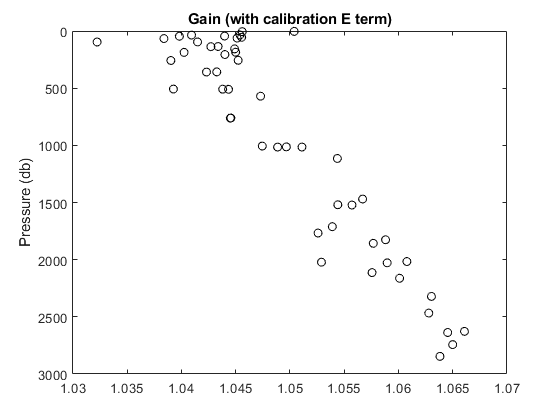

figure
plot(btlsum_yr9.Winkler_mLL./btlsum_yr9.Sbeox0ML_L,btlsum_yr9.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

% gain0_threshold = 1.025;
% gain0 = btlsum0.Winkler_mLL./btlsum0.Sbeox0ML_L;
% Wink_out = find(gain0 < gain0_threshold);
% btlsum0.Winkler_mLL(Wink_out) = NaN;

figure
plot(btlsum_yr9.Winkler_mLL./btlsum_yr9.Sbeox0ML_L,btlsum_yr9.PrDM,'o')
hold on
plot(btlsum0.Winkler_mLL./btlsum0.Sbeox0ML_L,btlsum0.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

cal.SOC = double(4.46780e-001);
cal.VOFFSET = double(-5.08600e-001);
cal.A = double(-5.00190e-003);
cal.B = double(2.51320e-004);
cal.C = double(-3.59380e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.22000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '1960';
cal.OCALDATE = '31-Jul-21';

H = [-0.033, 5000, 1450]; % Default 

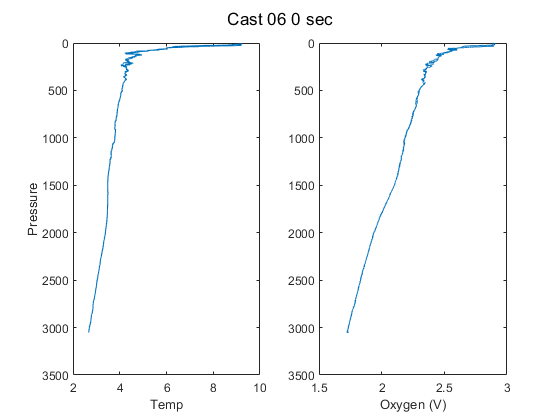

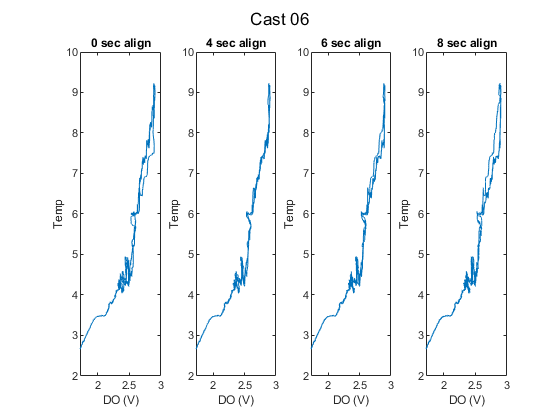

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 6; a3 = 8;

cast06 = align_CTD_KF(cast06,'Cast 06',a1,a2,a3);

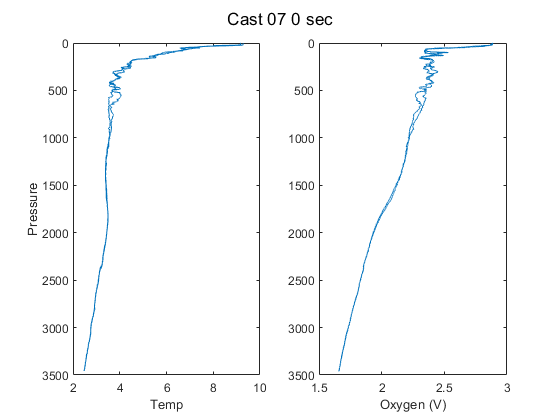

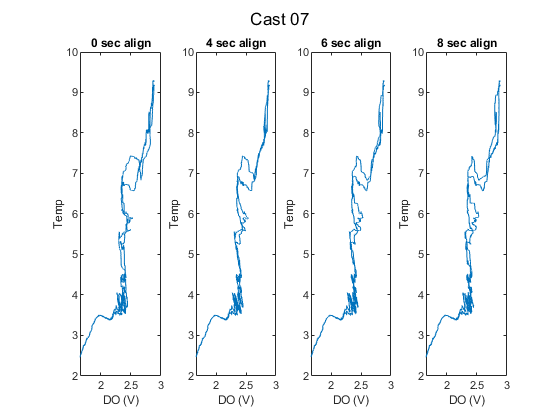

cast07 = align_CTD_KF(cast07,'Cast 07',a1,a2,a3);

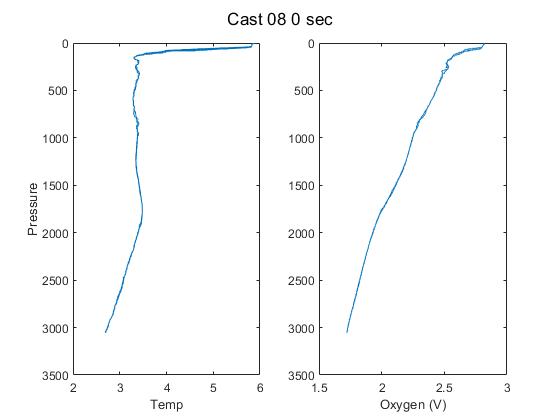

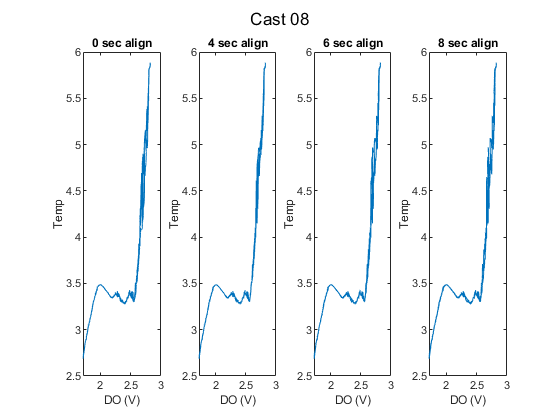

cast08 = align_CTD_KF(cast08,'Cast 08',a1,a2,a3);

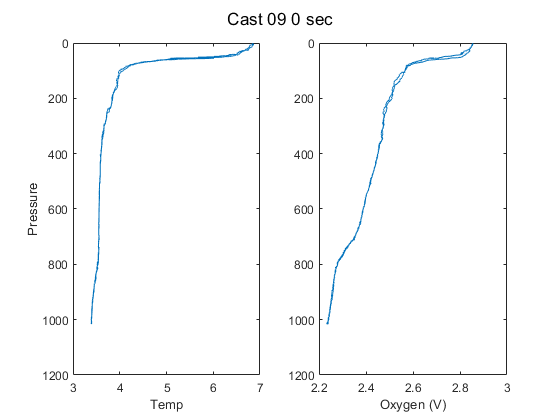

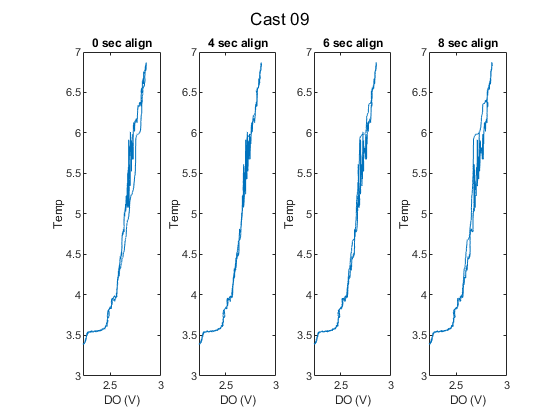

cast09 = align_CTD_KF(cast09,'Cast 09',a1,a2,a3);

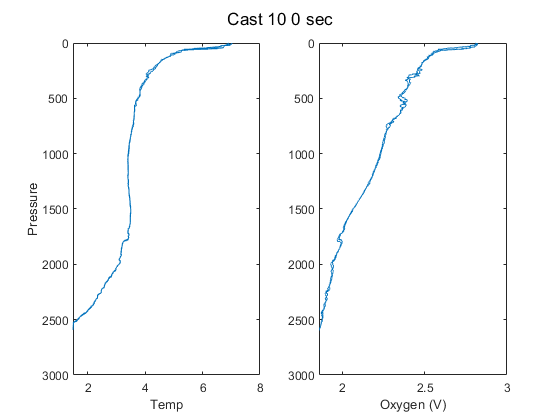

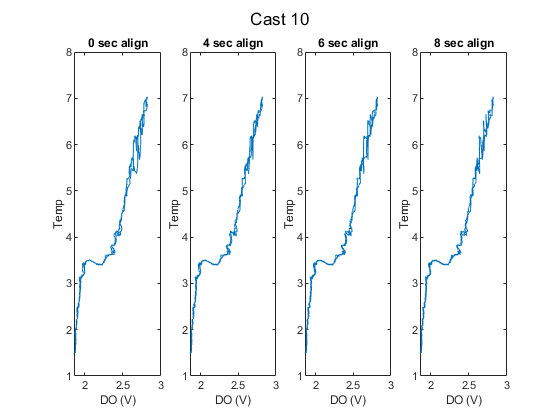

cast10 = align_CTD_KF(cast10,'Cast 10',a1,a2,a3);

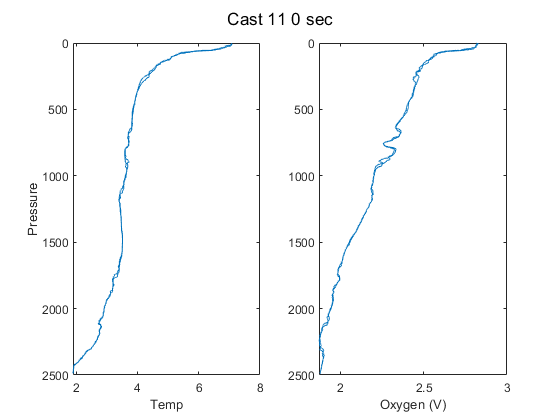

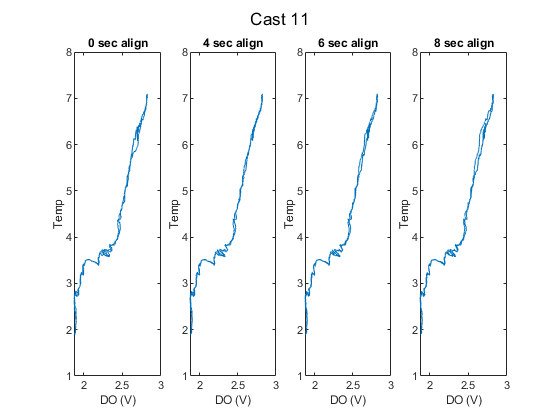

cast11 = align_CTD_KF(cast11,'Cast 11',a1,a2,a3);

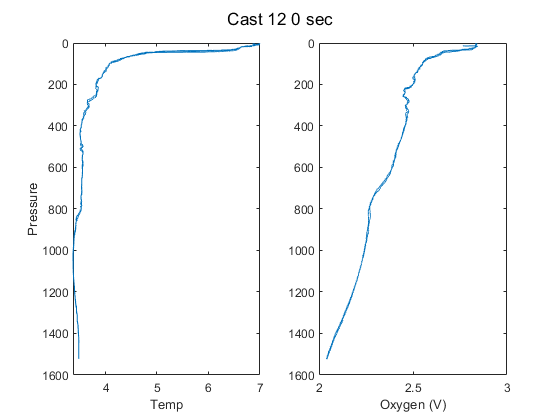

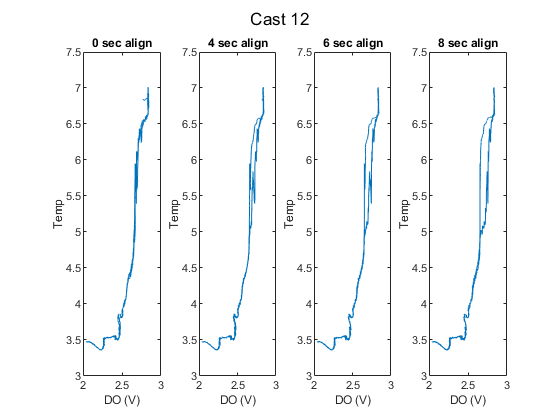

cast12 = align_CTD_KF(cast12,'Cast 12',a1,a2,a3);

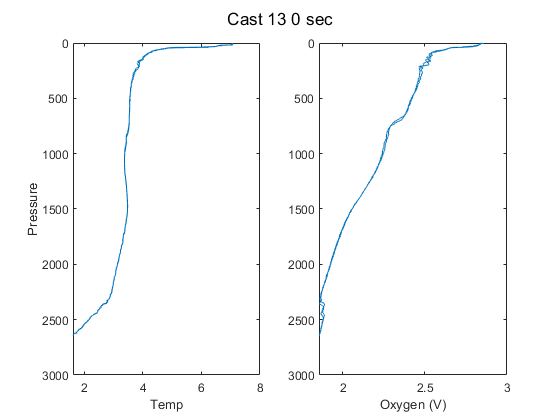

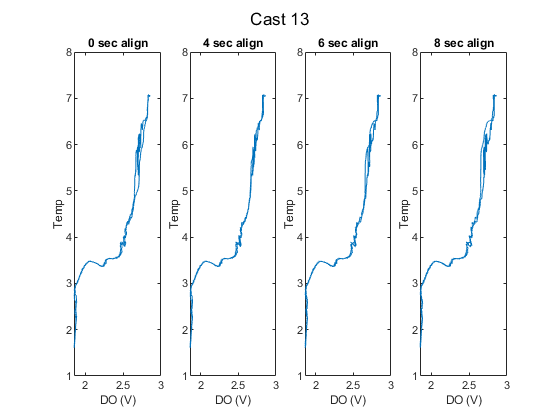

cast13 = align_CTD_KF(cast13,'Cast 13',a1,a2,a3);

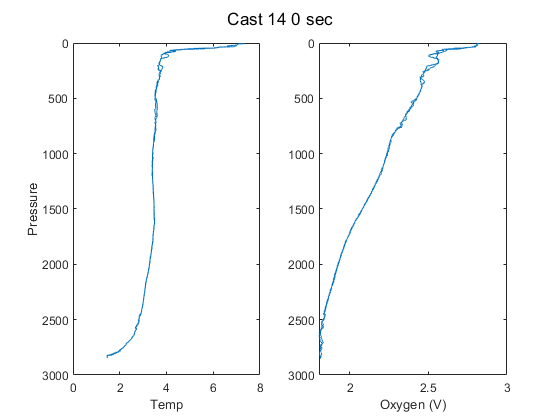

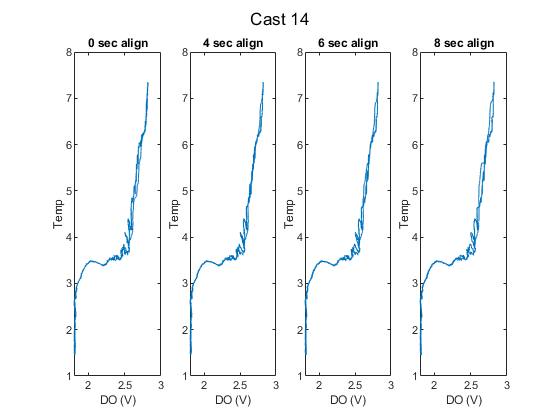

cast14 = align_CTD_KF(cast14,'Cast 14',a1,a2,a3);

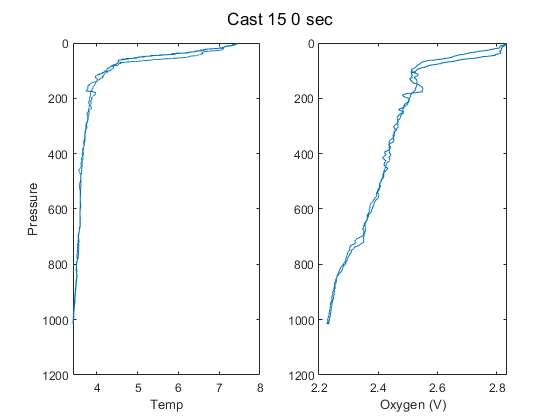

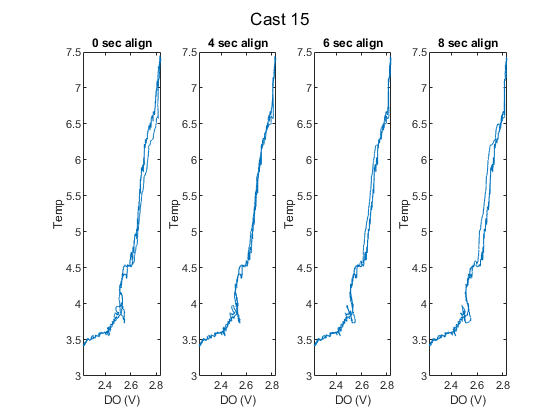

cast15 = align_CTD_KF(cast15,'Cast 15',a1,a2,a3);

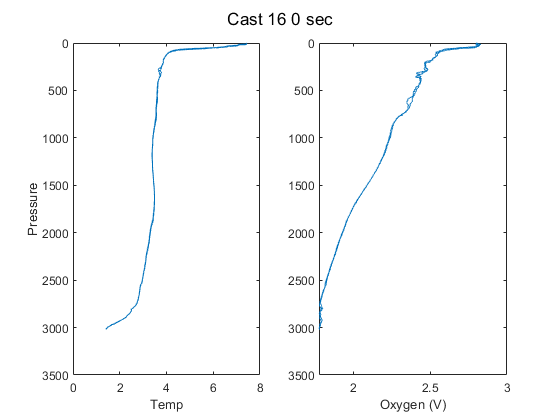

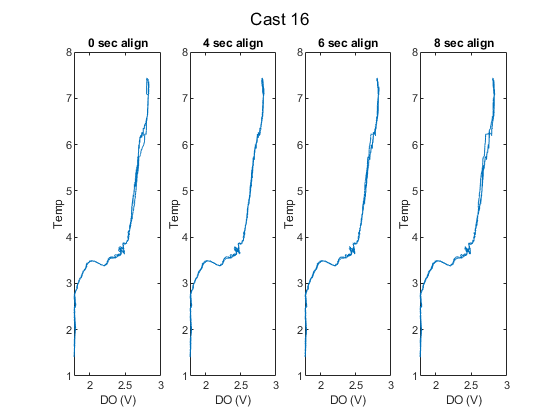

cast16 = align_CTD_KF(cast16,'Cast 16',a1,a2,a3);

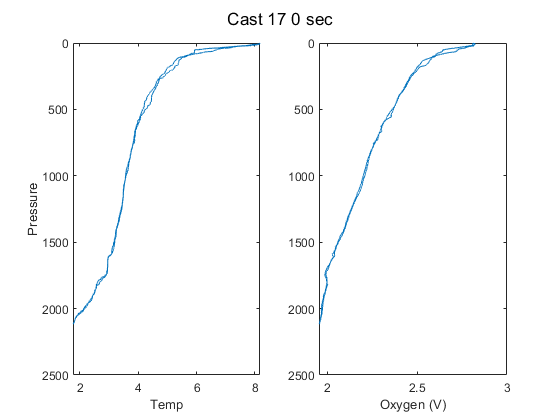

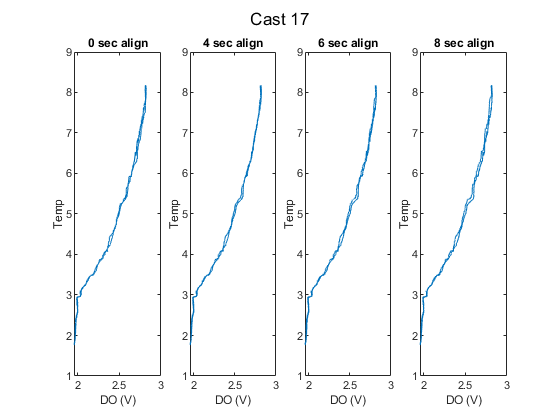

cast17 = align_CTD_KF(cast17,'Cast 17',a1,a2,a3);

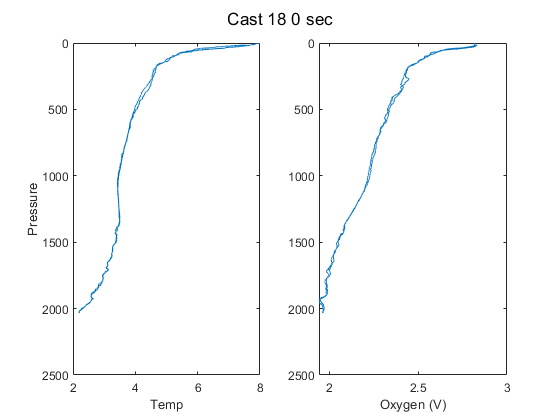

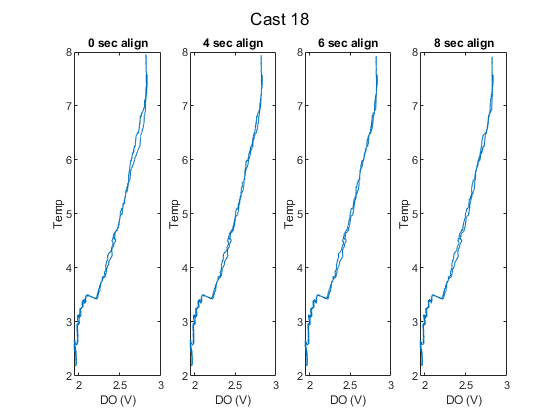

cast18 = align_CTD_KF(cast18,'Cast 18',a1,a2,a3);

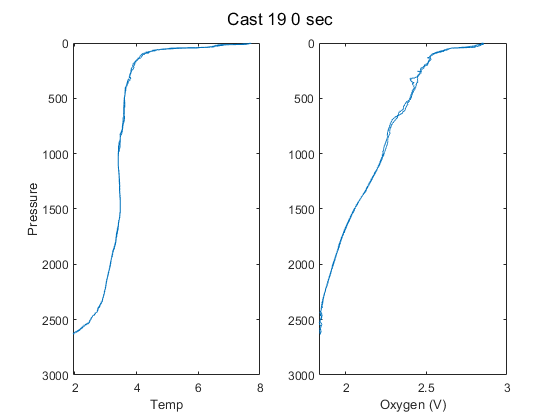

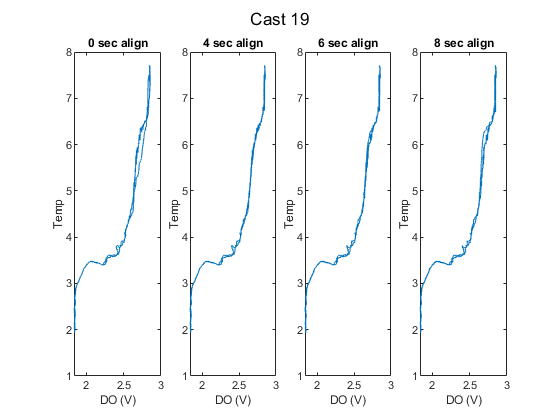

cast19 = align_CTD_KF(cast19,'Cast 19',a1,a2,a3);

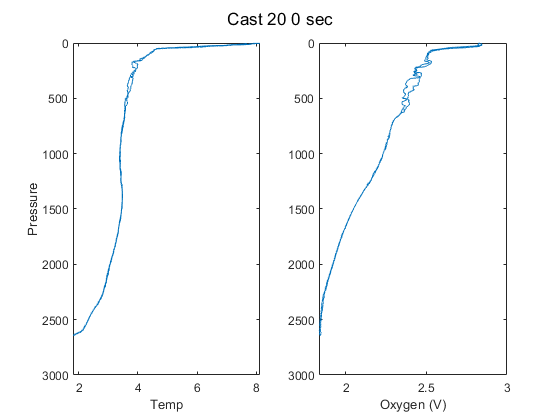

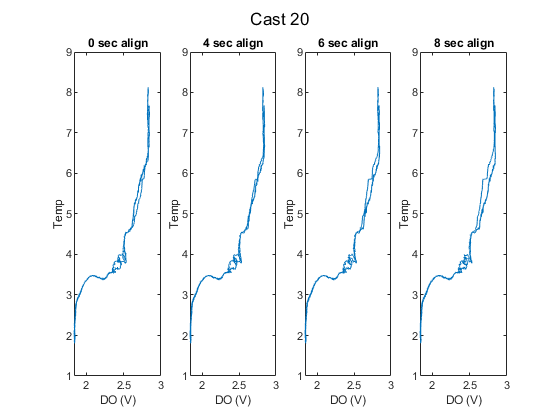

cast20 = align_CTD_KF(cast20,'Cast 20',a1,a2,a3);

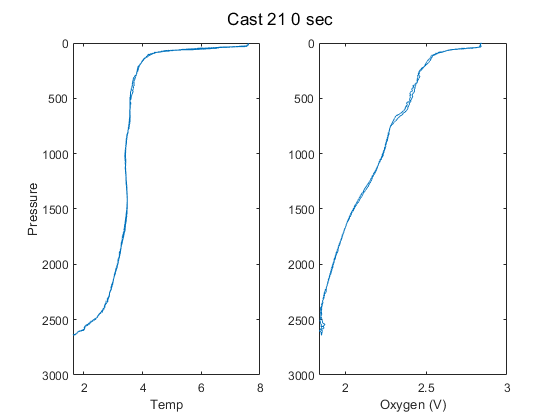

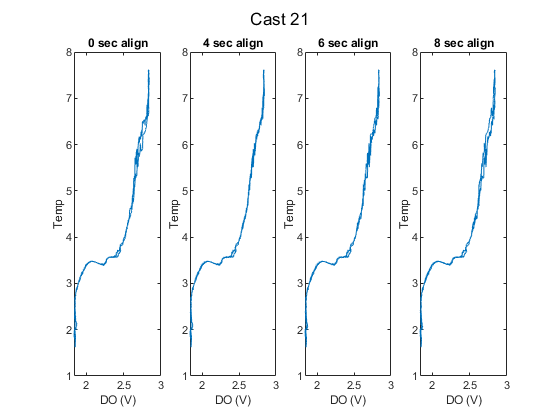

cast21 = align_CTD_KF(cast21,'Cast 21',a1,a2,a3);

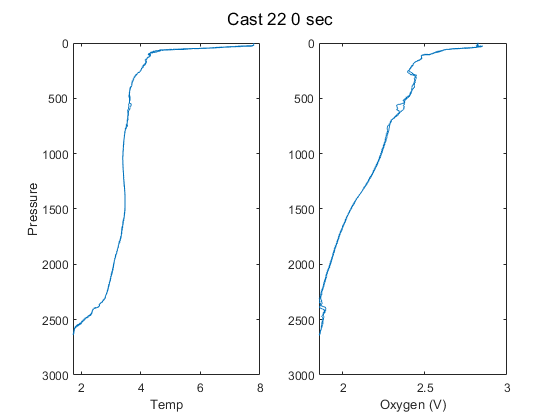

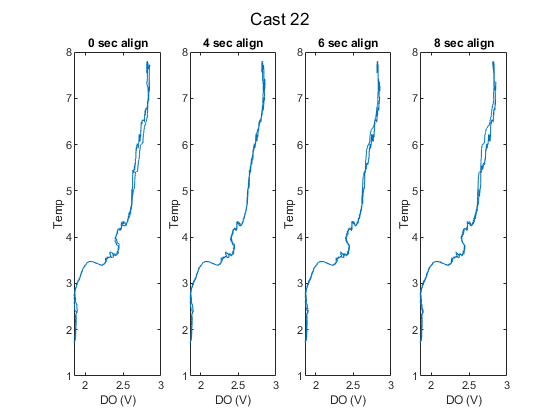

cast22 = align_CTD_KF(cast22,'Cast 22',a1,a2,a3);

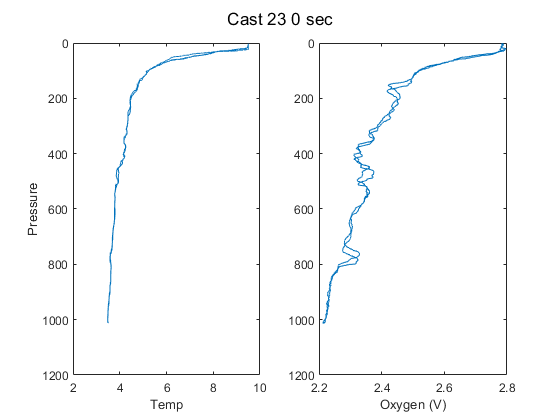

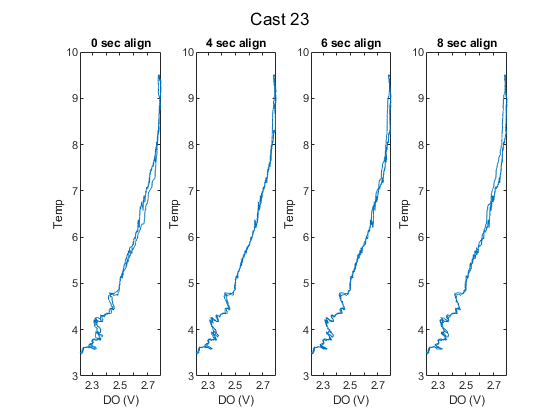

cast23 = align_CTD_KF(cast23,'Cast 23',a1,a2,a3);

% Pick align_sec
align_sec = 4;  % ***
%%% Pick up here. Process in SBE with 4 second alignmment 

% Read in processed casts
% Processed with 4 sec DO alignment and SBE cal hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')

cast06 = readSBScnv( 'uar69-01_006_hyst_abcdefg.cnv' );

Error using fgets
Invalid file identifier. Use fopen to generate a valid file identifier.

Error in fgetl (line 32)
[tline,lt] = fgets(fid);

Error in readSBScnv (line 59)
tline = fgetl(fid);

cast07 = readSBScnv( 'uar69-01_007_hyst_abcdefg.cnv' );
cast08 = readSBScnv( 'uar69-01_008_hyst_abcdefg.cnv' );
cast09 = readSBScnv( 'uar69-01_009_hyst_abcdefg.cnv' );
cast10 = readSBScnv( 'uar69-01_010_hyst_abcdefg.cnv' );
cast11 = readSBScnv( 'uar69-01_011_hyst_abcdefg.cnv' );
cast12 = readSBScnv( 'uar69-01_012_hyst_abcdefg.cnv' );
cast13 = readSBScnv( 'uar69-01_013_hyst_abcdefg.cnv' );
cast14 = readSBScnv( 'uar69-01_014_hyst_abcdefg.cnv' );
cast15 = readSBScnv( 'uar69-01_015_hyst_abcdefg.cnv' );
cast16 = readSBScnv( 'uar69-01_016_hyst_abcdefg.cnv' );
cast17 = readSBScnv( 'uar69-01_017_hyst_abcdefg.cnv' );
cast18 = readSBScnv( 'uar69-01_018_hyst_abcdefg.cnv' );
cast19 = readSBScnv( 'uar69-01_019_hyst_abcdefg.cnv' );
cast20 = readSBScnv( 'uar69-01_020_hyst_abcdefg.cnv' );
cast21 = readSBScnv( 'uar69-01_021_hyst_abcdefg.cnv' );
cast22 = readSBScnv( 'uar69-01_022_hyst_abcdefg.cnv' );
cast23 = readSBScnv( 'uar69-01_023_hyst_abcdefg.cnv' );

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
[cal] = E2_calculation(btlsum0,cal); % Use dummy bottle summary with outlier removed

[cal] = Gain_E2_Calculation(btlsum0,cal); % Use dummy bottle summary with any outliers removed

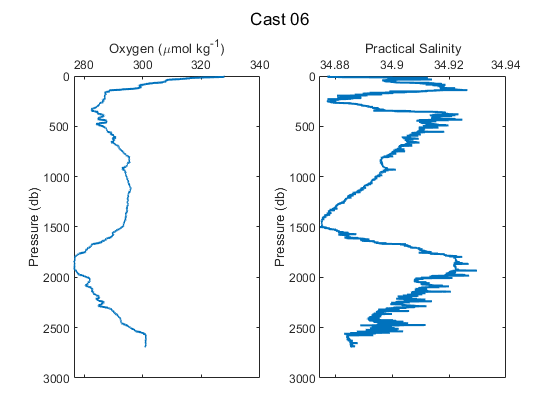

[cast06, btlsum06] = Process_Cast_Gain_E2(cast06,cal,0,1,'Cast 06');

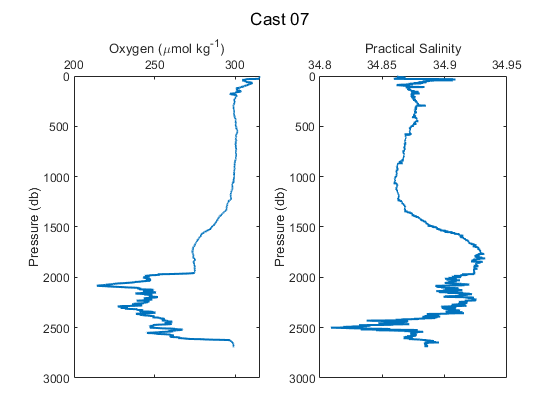

[cast07, btlsum07] = Process_Cast_Gain_E2(cast07,cal,0,1,'Cast 07');

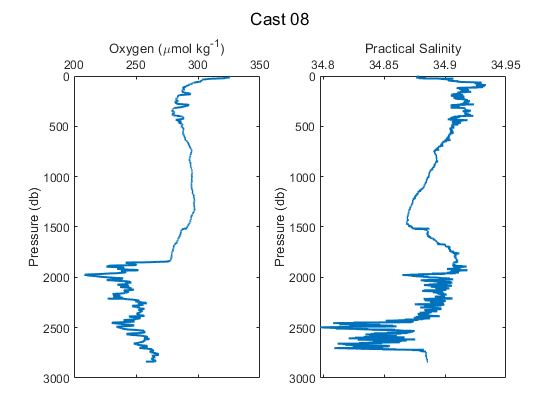

[cast08, btlsum08] = Process_Cast_Gain_E2(cast08,cal,0,1,'Cast 08');

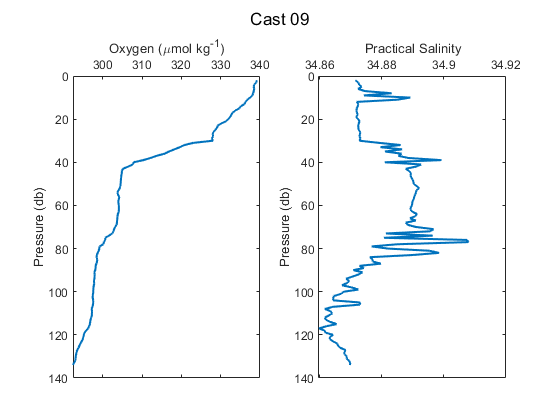

[cast09, btlsum09] = Process_Cast_Gain_E2(cast09,cal,0,1,'Cast 09');

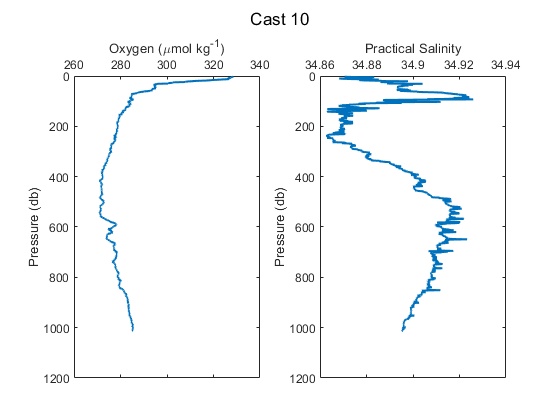

[cast10, btlsum10] = Process_Cast_Gain_E2(cast10,cal,0,1,'Cast 10');

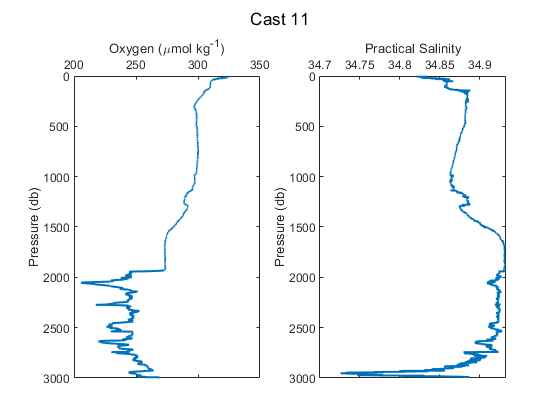

[cast11, btlsum11] = Process_Cast_Gain_E2(cast11,cal,0,1,'Cast 11');

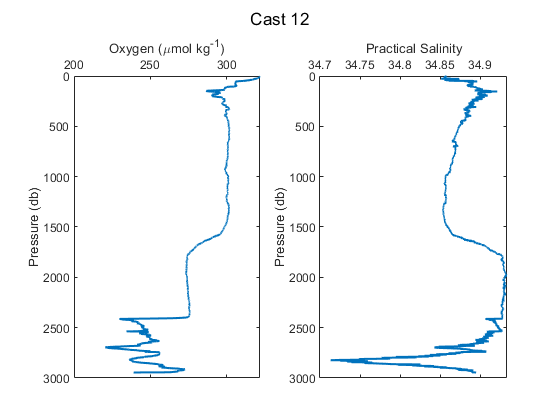

[cast12, btlsum12] = Process_Cast_Gain_E2(cast12,cal,0,1,'Cast 12');

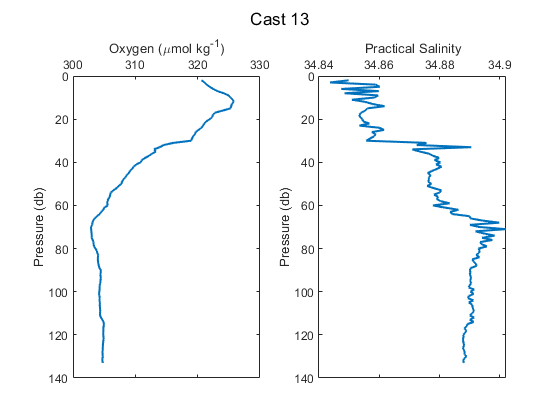

[cast13, btlsum13] = Process_Cast_Gain_E2(cast13,cal,0,1,'Cast 13');

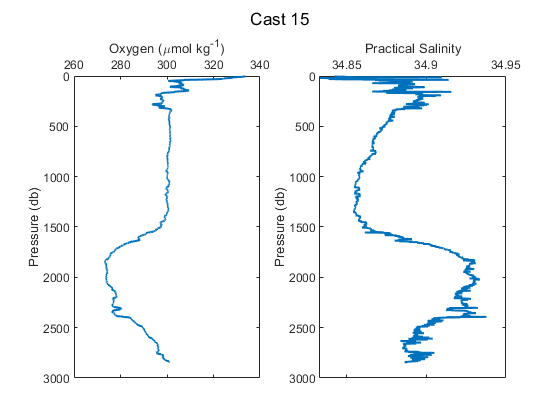

[cast14, btlsum14] = Process_Cast_Gain_E2(cast14,cal,btlsum14,1,'Cast 14');
[cast15, btlsum15] = Process_Cast_Gain_E2(cast15,cal,0,1,'Cast 15');

[cast16, btlsum16] = Process_Cast_Gain_E2(cast16,cal,btlsum16,1,'Cast 16');
[cast17, btlsum17] = Process_Cast_Gain_E2(cast17,cal,btlsum17,1,'Cast 17');
[cast18, btlsum18] = Process_Cast_Gain_E2(cast18,cal,btlsum18,1,'Cast 18');

Unrecognized function or variable 'btlsum18'.

[cast19, btlsum19] = Process_Cast_Gain_E2(cast19,cal,btlsum19,1,'Cast 19');
[cast20, btlsum20] = Process_Cast_Gain_E2(cast20,cal,btlsum20,1,'Cast 20');
[cast21, btlsum21] = Process_Cast_Gain_E2(cast21,cal,btlsum21,1,'Cast 21');
[cast22, btlsum22] = Process_Cast_Gain_E2(cast22,cal,0,1,'Cast 22');
[cast23, btlsum23] = Process_Cast_Gain_E2(cast23,cal,0,1,'Cast 23');


btlsum_yr9 = [btlsum14; btlsum16; btlsum17; btlsum18; btlsum19; btlsum20; btlsum21];

disp(['DO align (s) = ' num2str(align_sec)])
disp(['Cal. E term = ' num2str(cal.E)])
disp(['Adjust. E term (E2) = ' num2str(cal.E2)])
disp(['Cal SOC = ' num2str(cal.SOC)])
disp(['New SOC = ' num2str(cal.SOCnew) ])
disp(['E2Gain = ' num2str(cal.E2gain) '+/- ' num2str(cal.E2gainSTD)])


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')
clear btlsum0
dt_Processed = datetime;
save Year9_Processed_KF cast* btl* cal* dt_Processed 